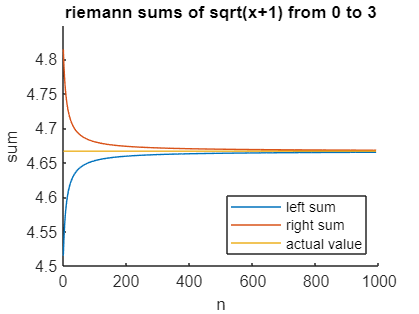

clc; clear; close all;

figure;
hold on;

a = 0;
b = 3;

num_iterations = 1000;

x_vals = 1:num_iterations - 9;
y_vals_left = nan(1, num_iterations - 9);
y_vals_right = nan(1, num_iterations - 9);

% calculate actual integral using fundamental theorem of calculus
actual_integral = (2/3)*(b+1)^(3/2) - (2/3)*(a+1)^(3/2);

true_vec = actual_integral .* ones(1, num_iterations - 9);

for n = 10:num_iterations
    deltaX = (b - a) / n;
    
    sum_left = sum(sqrt((a + (0:n-1) * deltaX) + 1) * deltaX);
    sum_right = sum(sqrt((a + (1:n) * deltaX) + 1) * deltaX);
    
    y_vals_left(n-9) = sum_left;
    y_vals_right(n-9) = sum_right;
end

% plotting
hold on;
plot(x_vals,y_vals_left);
plot(x_vals,y_vals_right);
plot(x_vals,true_vec);

legend("left sum", "right sum", "actual value", "Location", "Southeast");
xlabel("n");
ylabel("sum");
title("riemann sums of sqrt(x+1) from " + a + " to " + b);